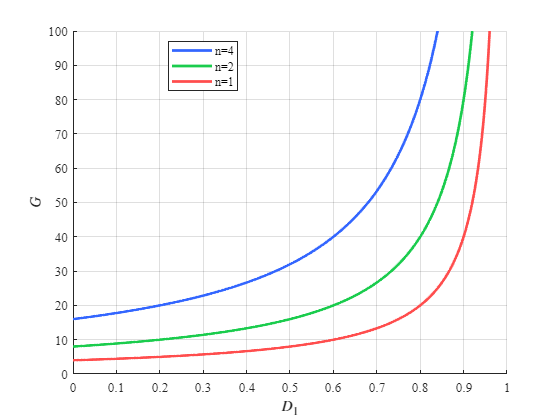

% 定义D的取值范围
D = linspace(0, 1, 1000);

% 定义n的值
n_values = [4, 2, 1];  % 重新调整n的顺序以便legend显示n=4, n=2, n=1

% 创建图形
figure;

% 绘制不同n对应的曲线
hold on;
for i = 1:length(n_values)
    n = n_values(i);
    G = 4 * n ./ (1 - D);  % 计算G的值
    plot(D, G, 'LineWidth', 2);  % 绘制曲线
end

% 设置不同的颜色
h = findobj(gca, 'Type', 'Line');
set(h(1), 'Color', [1, 0.3, 0.3]); % 柔和的红色
set(h(2), 'Color', [0.1, 0.8, 0.3]); % 柔和的绿色
set(h(3), 'Color', [0.2, 0.4, 1]); % 柔和的蓝色

% 添加标签和标题
xlabel('$\textit{D}_1$', 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel('$\textit{G}$', 'Interpreter', 'latex', 'FontName', 'Times New Roman');


% 设置x轴和y轴的范围
xlim([0, 1]);
ylim([0, 100]);

% 设置legend，顺序为 n=4, n=2, n=1
legend('n=4', 'n=2', 'n=1', 'Location', 'best', 'FontName', 'Times New Roman');

% 设置字体为Times New Roman
set(gca, 'FontName', 'Times New Roman');
grid on;
hold off;

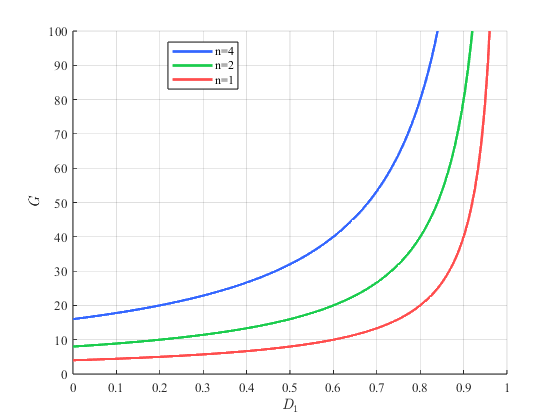

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'Voltage gain.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');